# ECM Fitting for lithium-ion batteries

## Abstract

Batteries become a central piece of electrification of our energy consumption, especially for transports. To improve their performances, innovation is getting faster and research is very active. But before building a battery, it's important to have an idea of how it will react in different condition, modeling appears useful. It is necessary to work on complex model who fit the best reality, but also to have powerful model a lot simpler. This model could give important informations as State of Charge or State of Health, without spending a lot of time, with the minimum complexity. 

We present a work on Equivalent Circuit Model to simulate a complete battery through only a few parameters. The battery management system needs the value of those parameters to be efficient. ECM are now the most used model for battery management systems.

## Getting the impedance from PXD Model (ECM PARAMETERISATION FROM PXD MODEL USING AUTOMATIC DIFFERENTIATION)

Obtaining the Impedance is a major part of the work, as we try to fit the impedance given by our parameters to the synthetic impedance from PXD Model.

We work with the state vector $$\mathcal{X}(t,x)$$ containing all the variables from the PXD model


$$
$\mathcal{X}(t,x)=[c_{\mathrm{ne}}(t,x),\phi_{\mathrm{ne}}(t,x),c_{\mathrm{elyte}}(t,x),\phi_{\mathrm{elyte}}(t,x),\ldots]$$$


The generic equation of the system is $\quad \frac{\partial\mathcal{M}(\mathcal{X})}{\partial t}+\mathcal{A}(\mathcal{X})=0.$ **(1)**

The operators $\mathcal{M}
$ and $\mathcal{A}$ are non-linear, but we dicretize it and $$\mathcal{X}(t,x)$$ becomes X(t) belonging to $$\mathbb{R}^{N}$$.

 Equation (1) becomes a non-linear system of **ordinary differential equations **: $\quad \frac{\partial M(X)}{\partial t}+A(X)=I(t)b(X)$.  ** (2)   ** 

Here I(t) is the current and b is mostly empty. He then uses an implicit method for the time discretization. He finds $$X^{n+1}$$ with $$X^{n}$ at time step $n$$ solving the equation for the unknown X : $\frac{M(X)-M(X^{n})}{\Delta t}+A(X)=b(X)I(t^{n+1})$.

Then he linearize around a state given by $$X_{0}$ $with a small perturbation $$\delta X=X-X_{0}$$. $$A(X)$$ becomes$A(X)=A(X_{0})+D_{A}(X_{0})\delta X$ with $$D_{A}$$ the Jacobian of A. The same process for M and B ($$D_{M}$ and $D_{b}$$ being their jacobians) gives this linear system of ordinary differential equations :

$\quad D_{M}\frac{\partial}{\partial t}\delta X+A(X_{0})+D_{A}\delta X=I(t)b(X_{0})+I(t)D_{b}\delta X.$ **(3)**

$$X_{0}$$ is solution to the steady-state problem $I(t)=0$, which implies $A(X_{0})=0$. Also $$\delta X \ll 1$ implies $I(t)b(X_{0}) \gg I(t)D_{b}(X_{0})\delta X$$ so he neglects the last term. 

The final equation is now $\quad D_{M}\frac{\partial}{\partial t}\delta X+D_{A}\delta X=I(t)b_{0}$.   **(4)**

The Fourier transform of this equation is$\quad [i\omega D_{M}+D_{A}]\overline{\delta X}=\bar{I}b_{0}
$  **(5)** with $I(t)=\bar{I}e^{i\omega t}\text{ and }\delta X=\overline{\delta X}e^{i\omega t}.$

So $\overline{\delta X} =\left[i\omega D_{M}+D_{A}\right]^{-1}b_{0}\bar{I}$.   **(6)**

There is a certain vector $r$ so that $U=r^{t}X$, $U$ being the voltage response.

$U=r^{t}X_{0}+r^{t}\delta X$ so $U-U_{0}=\bar{U}e^{i\omega t}$ with $$U_{0}=r^{t}X_{0}$$. 

It comes from **(6) ** that 


$$\bar{U} =r^{t}\overline{\delta X} $$



$$\bar{U} = r^{t}\left[i\omega D_{M}+D_{A}\right]^{-1}b_{0}\bar{I}$$


At the end it gives $Z(\omega)=r^{t}\left[i\omega D_{M}+D_{A}\right]^{-1}b_{0}$.

## ECM Presentation

### Objective

Effective everyday operation of a battery requires the Battery Management System (BMS) to continuously monitor its real-time state (State of Charge, State of Health). Given the practical challenges of measuring this state via chemical methods, modeling offers a useful alternative. By identifying the parameters of the Equivalent Circuit Model (ECM) in real-time, valuable information about the system can be extracted. Because each set of parameters maps to a specific physical state, determining the state simply becomes a matter of referencing a lookup table.

### Theory

A battery can be modelled by an Open Circuit Voltage (OCV) which is a perfect source of current. This is the simpliest way to simulate it. One can realize that it is necessary to get a bit deeper in the analysis, with the add of a resistor, which symbolizes the heat dissipation. This model remains very simple, it is possible to add the diffusion phenomena with a serie of n parallel resistor and capacitance. It is the n-Thevenin model.

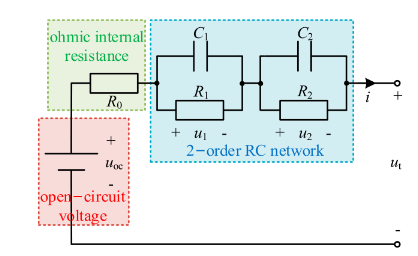

Example of a 2-Thevenin Model ([Sun, comprehensive review of ECM](https://www.mdpi.com/2079-9292/15/9/1968))

It is a good compromise to have 2 RC networks, because the model remains simple but allows two different time-scaled phenomenon. However another flaw of this model is the symetry of the two pairs, identifiability becomes a lot harder.

The impedance of this circuit is $Z = R_0 + \frac{R_1}{1 + j R_1 C_1 \omega} + \frac{R_2}{1 + j R_2 C_2 \omega}$.

Another way to modelize diffusion is with a Warburg component, which has the impedance $Z_W = \frac{1}{Y_0 \sqrt{j\omega}}$ and adds to the Nyquist diagram a 45° slope for low frequencies. A Warburg element is the equivalent of an infinity of capacitance/resistor pairs

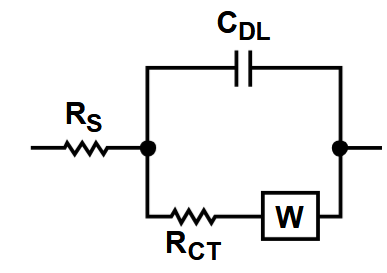

Warburg circuit model ([Analog devices](https://www.analog.com/media/en/reference-design-documentation/reference-designs/cn0510.pdf), 2021)

Some researchers, as Santoni in his [paper](https://www.sciencedirect.com/science/article/pii/S2352152X2303788X), have tried some other similar circuits with more accurate tools, but further from basic electronical elements. He replaced capacitors by constant phase elements (CPE), adding an $\alpha$-parameterto quantify non ideality. The impedance is $Z=\frac{1}{Q{\left(j\omega \right)}^{\alpha } }$.  $\alpha =1$ would make it an ideal capacitor, $\alpha =0\ldotp 5$ is for a Warburg element.

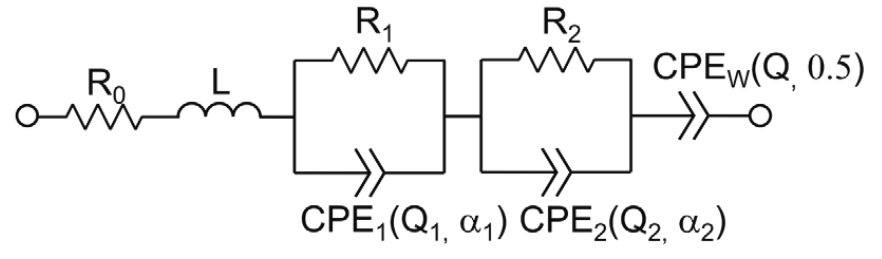

A 2nd-Order model with CPE used by Santoni

### Physical Meaning of ECM components ([Analog devices](https://www.analog.com/media/en/reference-design-documentation/reference-designs/cn0510.pdf), 2021)

ECM are built after the Occam's razor principles, to which each component has to be linked to a physical phenomena of the battery ([Fletcher](https://link.springer.com/article/10.1007/s10008-013-2328-4) 2013):

**The Ohmic Resistance ** corresponds to the internal resistance of the battery, and explains its heating during use. The Resistance increases with the battery ageeing.

**The first RC pair ** is linked to charge transfer between the electrode and the electrolyte. R is the physical resistance that electrons face when they change state, from solid electrode to liquid electrolyte. C is the double layer capacitance, composed of two parallel layers of opposite charge. This pair is dominant for frequencies between 1 Hz and 1 kHz, and is represented by the "bump" one can observe in middle frquencies.

**The second RC pair or Warburg element **is a lot bigger in value than the first one, and represents a slower phenomenon, the mass transfer linked to diffusion of Lithium ions. This is the 45° phase shift that one can see in low frequencies, where it is the dominating process as the slowest one. 

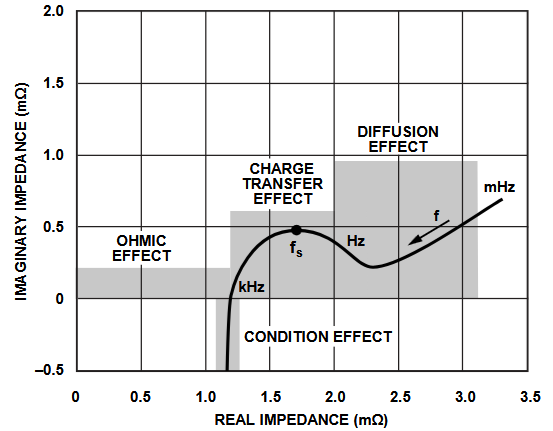

Electrochemical processes linked to EIS regions ([Analog devices](https://www.analog.com/media/en/reference-design-documentation/reference-designs/cn0510.pdf), 2021)

### Impact on Impedance of physical parameters from PXD model

The parameters from the study of Chen 2020 were chosen to build the PXD Battmo model. We tried to modify them to understand better their impact on the impedance diagram.

The experimental impedance dtat is obtained thanks to EIS. The Electrochemical Impedance Spectroscopy is a highly sensitive, non-destructive analytical technique used to study the internal dynamics of an electrochemical system, such as a lithium-ion battery. It works by applying a small alternating current (AC) voltage (or current) to the system across a wide range of frequencies—from very high (thousands of Hertz) to very low (fractions of a Hertz)—and measuring the resulting current (or voltage) response and phase shift. 

EIS allows the approximation of one single state as the variations are very small in the same time as it makes it possible to study the Fourier transform.

By observing how the battery responds at specific frequency ranges, scientists can diagnose its internal mechanics. High frequencies allow measure the pure ohmic or electrical resistance of the battery components, medium frequencies show the charge transfer resistance, low frequencies highlight mass transport and diffusion, indicating how fast the lithium ions are traveling into and through the solid electrode particles.

% --- Initialisation  ---
mrstModule add ad-core mrst-gui mpfa agmg linearsolvers

jsonstruct_material = parseBattmoJson(fullfile('ParameterData','ParameterSets','Chen2020','chen2020_lithium_ion_battery.json'));
jsonstruct_geometry = parseBattmoJson(fullfile('Examples', 'JsonDataFiles', 'geometryChen.json'));
jsonstruct_base = mergeJsonStructs({jsonstruct_material, jsonstruct_geometry});

jsonstruct_base.NegativeElectrode.Coating.ActiveMaterial.Interface.useDoubleLayerCapacity = true;

c_ne = 29.866*mol/litre; 
c_pe = 17.038*mol/litre; 

disp('Initialisation done');

Initialisation done


This sliders allow logarithmic changes: new_val = val_init * 10^p.

Computing ...


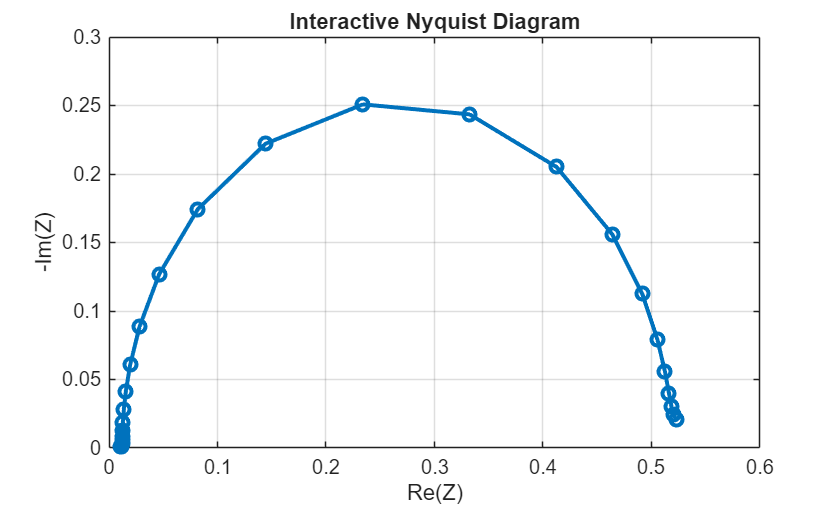

Calculation succeeded


p_diffusion = 0;
p_reactionRate = -2;
p_doubleLayerCapacitance = 0;
base_diff_anode = 1.3135e-15;
base_rate_anode = 5.031e-11;
base_cdl = 0.2;


val_diff_anode = base_diff_anode * (10^p_diffusion);
val_rate_anode = base_rate_anode * (10^p_reactionRate);
val_cdl = base_cdl * (10^p_doubleLayerCapacitance);


jsonstruct = jsonstruct_base;


jsonstruct.NegativeElectrode.Coating.ActiveMaterial.SolidDiffusion.referenceDiffusionCoefficient = val_diff_anode;
jsonstruct.NegativeElectrode.Coating.ActiveMaterial.Interface.reactionRateConstant = val_rate_anode;
jsonstruct.NegativeElectrode.Coating.ActiveMaterial.Interface.doubleLayerCapacitance = val_cdl;


try
    disp('Computing ...');
    
    [model, inputparams, ~] = setupModelFromJson(jsonstruct);
    initstate = initStateChen2020(model, c_ne, c_pe);
    
    impsolv = ImpedanceSolver(inputparams, 'initstate', initstate, 'computeSteadyState', false);

    frequences = logspace(-2, 3, 30); 
    Z = impsolv.computeImpedance(frequences);
    
    figure('Name', 'Nyquist Diagram');
    plot(real(Z), -imag(Z), '-o', 'LineWidth', 2, 'Color', '#0072BD');
    grid on;
    xlabel('Re(Z)');
    ylabel('-Im(Z)');
    title('Interactive Nyquist Diagram');
    
    disp('Calculation succeeded');
    
catch ME
    disp('--- ERROR ---');
    disp(ME.message);
end

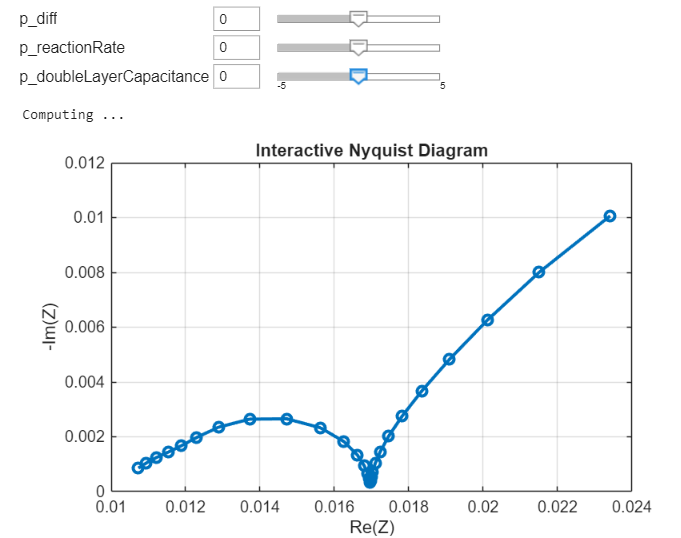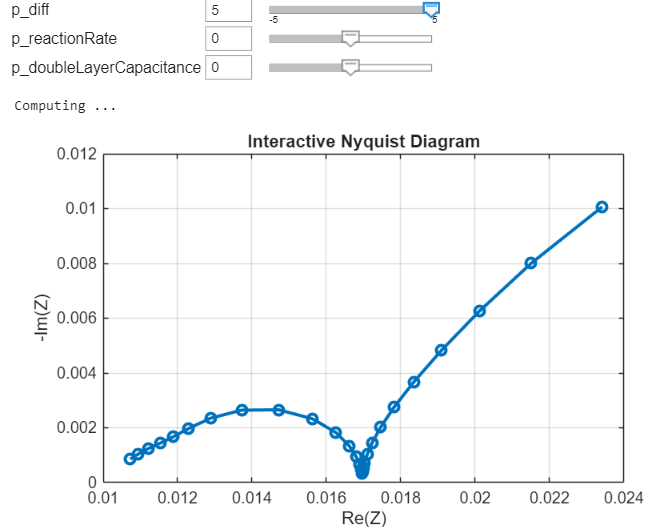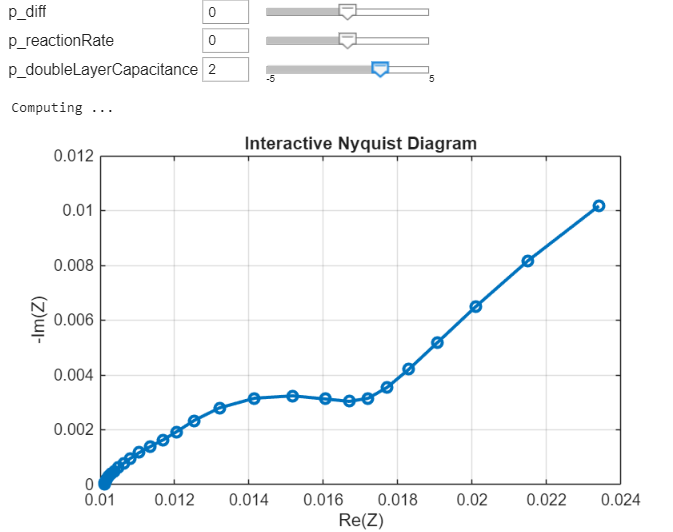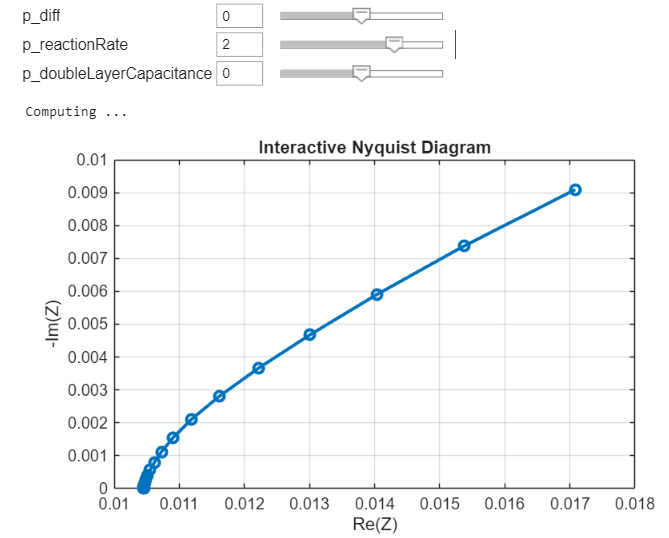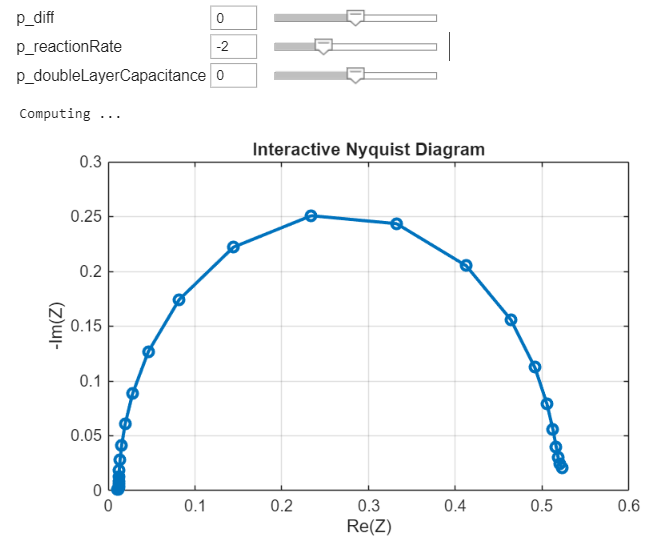

## Calibration of ECM parameters

We tried through optimization to fit different models to ECM through five parameters, $R_0$, $R_1$, $C_1$, $R_2$ and $C_2$. 

We chose unitBoxBFGS as optimization algorithm, which allows other constraints. As the two RC parallel cells are symetric, we imposed $C_1 > 2*C_2$ to ensure robustness and injectivity of the optimization. Thanks this criteria, a particular battery state always lead to the same equivalent circuit.

UnitBoxBFGS needs to work in a bok between 0 and 1. We chose to work between two vectors pmax and pmin, framing initial values, and to normalize them so that pmin becomes 0 and pmax becomes 1.

function p_norm = unscaled2scaled(feis, p)
    pmin = feis.scales(1:5);
    pmax = feis.scales(6:10);
    p_norm = (p-pmin)./(pmax-pmin);
end

function p = scaled2unscaled(feis, p_norm)
    pmin = feis.scales(1:5);
    pmax = feis.scales(6:10);
    p = (pmax-pmin).*p_norm +pmin;
end


function [min_value, history, best_params, fitting_error] = optimizationBFGS(feis)
            

            f_opt = @(p_norm) feis.optifunc(scaled2unscaled(feis, p_norm));
            
            params0_norm = unscaled2scaled(feis, feis.params0);
            % best_params_norm = lsqnonlin(deltagap, params0_norm, lb_norm, ub_norm, [0,0,-1,0,10], 0);
            params0_norm = params0_norm(:);
           
            pmin = feis.scales(1:5);
            pmax = feis.scales(6:10);
            p03min = pmin(3);
            p03max = pmax(3);
            p05min = pmin(5);
            p05max = pmax(5);

            A_custom = [0, 0, -1, 0, 2*(p05max - p05min)/(p03max- p03min)];
            b_custom = (p03min-2*p05min)/(p03max - p03min);
            
            max_iter = 300;
            tol_obj = 1e-15;
            tol_grad = 1e-5;

            [min_value, best_params_norm, history] = unitBoxBFGS(...
                params0_norm, ...                             
                f_opt, ...           
                'maximize', false, ...      
                'linIneq', struct('A', A_custom, 'b', b_custom),  ...   %A*u<=b
                'enforceFeasible', true, ...     
                'maxIt', max_iter, ...               
                'objChangeTol', tol_obj, ...       
                'gradTol', tol_grad, ...
                'lineSearchMaxIt', 100 ...
                                                                );
            best_params = scaled2unscaled(feis, best_params_norm(:) );

            % explications of why it stopped
            fitting_error = feis.optifunc(best_params);

            it_count = length(history.val) - 1; 
            final_pg = history.pg(end);         
            
            % Cost function variation
            if it_count >= 1
                delta_v = abs(history.val(end) - history.val(end-1));
            else
                delta_v = inf;
            end
            
            if it_count >= max_iter
                fprintf('Stopped because %d iterations reached.\n', max_iter);
            elseif final_pg < tol_grad
                fprintf('Stopped because reached gradTol = %e.\n', tol_grad);
            elseif delta_v < tol_obj
                fprintf('Stopped because reached objChangeTol = %e.\n', tol_obj);
            else
                fprintf('Unexpected error or relative tolerance reached.\n');
            end           


        end

        

        function [v, g_norm] = optifunc(feis, p)
            
            % Preventing physical values to get too close from 0
            p_safe = max(p, 1e-8);

            [Z_re_param, Z_im_param] = load_nyquist(p_safe, feis.omega);


            if istable(Z_re_param), Z_re_param = table2array(Z_re_param); end
            if istable(Z_im_param), Z_im_param = table2array(Z_im_param); end
            
           
            Z_re_param = double(Z_re_param(:));
            Z_im_param = double(Z_im_param(:));


            if ~isnumeric(Z_re_param) || ~isreal(Z_re_param) || any(isnan(Z_re_param(:)))
                v = 1e10; 
                g_norm = zeros(5,1); 
                return;
            end
            
            Modulus_Z = sqrt(feis.Z_re_exp.^2 + feis.Z_im_exp.^2);
            Modulus_Z = Modulus_Z(:);
            
            err_re = (feis.Z_re_exp(:) - Z_re_param(:)) ./ Modulus_Z(:);
            err_im = (feis.Z_im_exp(:) - Z_im_param(:)) ./ Modulus_Z(:);
            
            v = sum(err_re.^2 + err_im.^2);


            if nargout > 1

                w  = feis.omega(:);
                R0 = p_safe(1);
                R1 = p_safe(2);
                C1 = p_safe(3);
                R2 = p_safe(4);
                C2 = p_safe(5);

                g_re_dR0 = -ones(size(w)); 
                g_re_dR1 = -(1-(R1*C1.*w).^2) ./ (1+(R1*C1.*w).^2).^2;  
                g_re_dC1 = (2*C1*R1^3.*w.^2) ./ (1+(R1*C1.*w).^2).^2;  
                g_re_dR2 = -(1-(R2*C2.*w).^2) ./ (1+(R2*C2.*w).^2).^2;  
                g_re_dC2 = (2*C2*R2^3.*w.^2) ./ (1+(R2*C2.*w).^2).^2;

                J_re = [g_re_dR0, g_re_dR1, g_re_dC1, g_re_dR2, g_re_dC2];

                g_im_dR0 = zeros(size(w));
                g_im_dR1 = (2*R1*C1.*w) ./ (1+(R1*C1.*w).^2).^2;  
                g_im_dC1 = (R1^2.*w - C1^2*R1^4.*w.^3) ./ (1+(R1*C1.*w).^2).^2;  
                g_im_dR2 = (2*R2*C2.*w) ./ (1+(R2*C2.*w).^2).^2;  
                g_im_dC2 = (R2^2.*w - C2^2*R2^4.*w.^3) ./ (1+(R2*C2.*w).^2).^2; 

                J_im = [g_im_dR0, g_im_dR1, g_im_dC1, g_im_dR2, g_im_dC2];
                derr_re_dp = J_re ./ Modulus_Z; 
                derr_im_dp = J_im ./ Modulus_Z;

                g_true = 2 * (derr_re_dp' * err_re) + 2 * (derr_im_dp' * err_im);
                % Chain rule : 
                pmin = feis.scales(1:5);
                pmax = feis.scales(6:10);
                dp_dpnorm = (pmax - pmin);      % Dérivée de p par rapport à p_norm
                g_norm = g_true .* dp_dpnorm;
               
                
            end
        end 

### Algorithm performance check

In order to check the algorithm's accuracy, we fitted synthetic results from a 2-Thevenin Model.

It:  0 | val: 1.373e-31 | ls-its: NaN | pgrad: 1.164e-12
It:  1 | val: 1.373e-31 | ls-its:   0 | pgrad: 1.152e-12
Stopped because reached gradTol = 1.000000e-05.


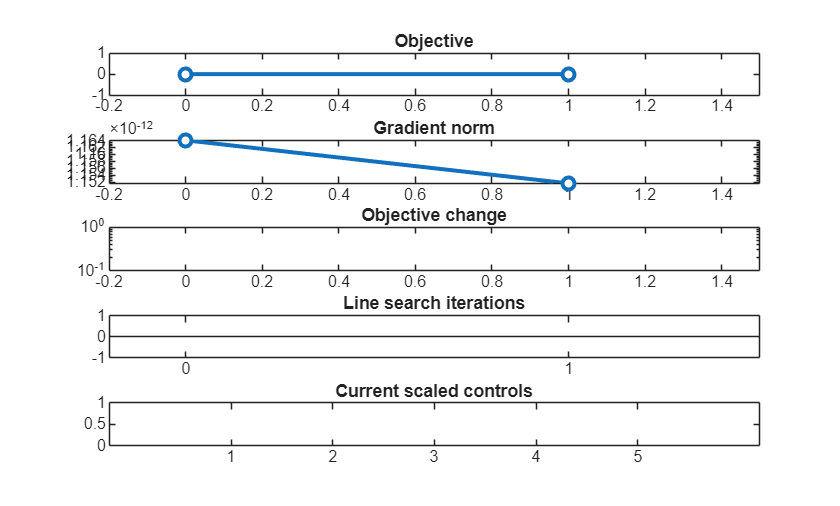

omega = logspace(-4, 2, 50);
params = [0.05052, 1.12673, 59119.9, 0.03155, 11054.0];
[Z_re_exp, Z_im_exp] = load_nyquist(params, omega);



function [Z_real, Z_imag] = load_nyquist(params, omega)

    R_0 = params(1);
    R_1 = params(2);
    C_1 = params(3);
    R_2 = params(4);
    C_2 = params(5);
    
    
    
    Z_real = R_0 +    R_1 ./ (1+(R_1* C_1.*omega).^2)    +   R_2 ./ (1+(R_2* C_2.*omega).^2);
    Z_imag = -(R_1*R_1*C_1.*omega ./ (1+(R_1* C_1.*omega).^2))  ...
               - (R_2*R_2*C_2.*omega ./ (1+(R_2* C_2.*omega).^2));

end



params0 = [0.05052, 1.12673, 59119.9, 0.03155, 11054.0];  % initial condition: C1>2*C2

a = 1000;

pmin = params0 / a;
pmax = params0 * a;
scales = [pmin, pmax];

feis = FittingEIS(params0, scales, Z_re_exp, Z_im_exp, omega);

[~, ~, best_params, fitting_error] = feis.optimizationBFGS();

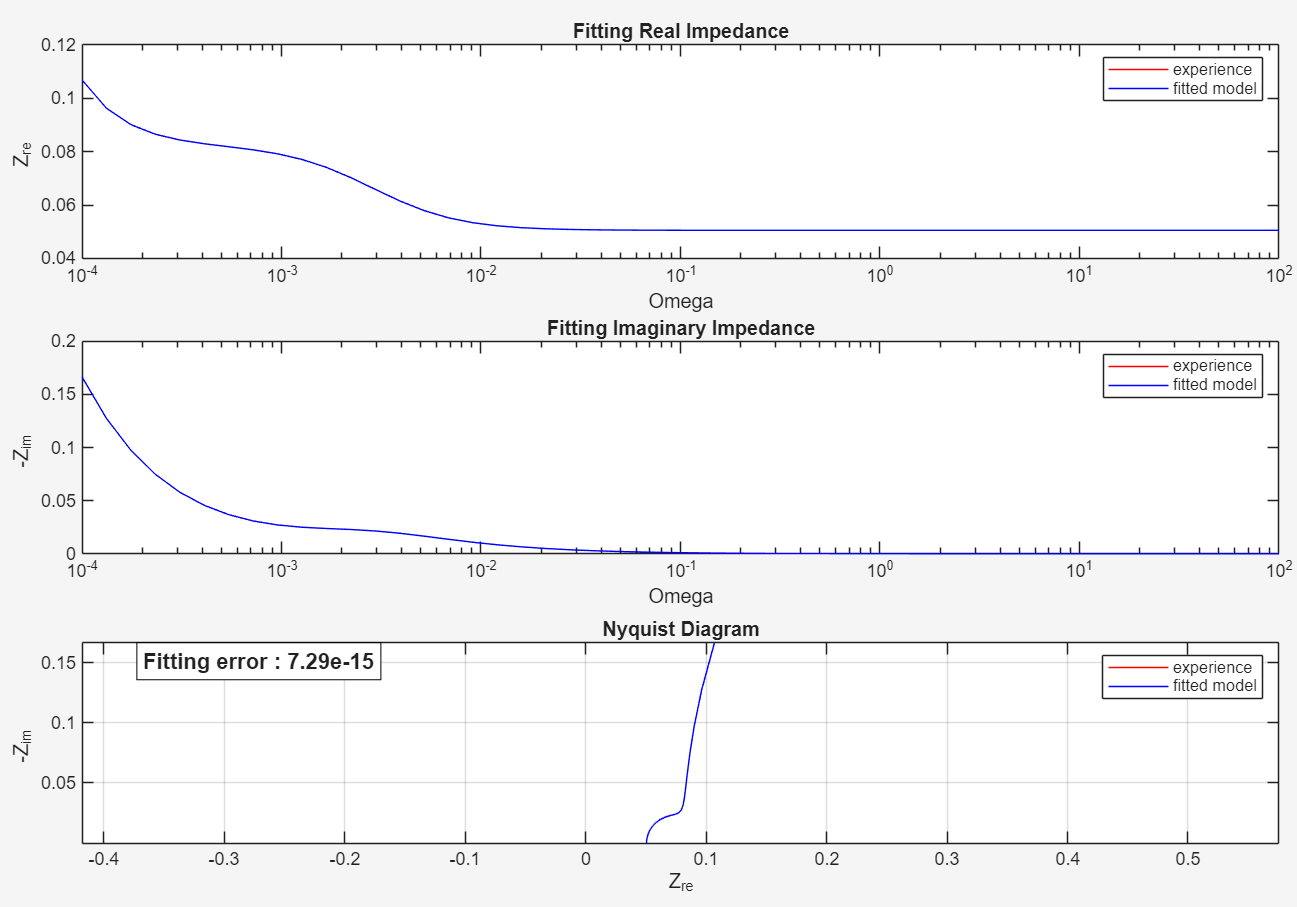

To assess the robustness of the optimization algorithm, we evaluated its performance under varying initial conditions. The initial parameters were randomly sampled within a broad range, bounded between the target parameters divided by a scaling factor **a** and the target parameters multiplied by **a**. This procedure was repeated five times for each configuration. 

For scaling factors of $a = 100$ and $a = 500$, the algorithm proved to be robust, successfully converging to the optimal solution without any issues. However, at a scaling factor of $a = 1000$, the algorithm failed to converge, resulting in a MATLAB assertion error. The algorithm triggers a safety assertion (`d'*g0 <= 0`) to prevent taking an invalid, non-descending optimization step.

### Fitting experimental data

Then we tried to match the experimental data from Ank's work ([paper](https://iopscience.iop.org/article/10.1149/1945-7111/ad14d0#jesad14d0s2)). Ank managed to find the Impedance depending on the state of charge through electrochemical impedance spectroscopy. They studied the 4680 cell format (46 mm diameter, 80 mm axial length) which is used for the Tesla Model Y electric vehicle (year of manufacture 2022).

function [Z_real, Z_imag, omega] = load_experimental_data(filename)
    
    opts = detectImportOptions(filename, 'Delimiter', '\t');

    opts.VariableNamesLine = 1;
    opts.DataLine = 2;
    opts.VariableNamingRule = 'preserve';
    data = readtable(filename, opts);
    colNames = data.Properties.VariableNames;
    

    idx_real = contains(colNames, 'Re(Z)', 'IgnoreCase', true);
    idx_imag = contains(colNames, 'Im(Z)', 'IgnoreCase', true);
    idx_freq = contains(colNames, 'freq', 'IgnoreCase', true);
    
    Z_real_raw = data{:, idx_real}; 
    Z_imag_raw = data{:, idx_imag};
    freq_raw  = data{:, idx_freq};

    if iscell(Z_real_raw) || isstring(Z_real_raw)
        Z_real = str2double(strrep(Z_real_raw, ',', '.'));
        Z_imag = str2double(strrep(Z_imag_raw, ',', '.'));
        freq  = str2double(strrep(freq_raw, ',', '.'));
    else
        Z_real = Z_real_raw;
        Z_imag = Z_imag_raw;    
        freq  = freq_raw;
    end

    idx_valides = (Z_real ~= 0) & ~isnan(Z_real);
    Z_real = Z_real(idx_valides);
    Z_imag = -Z_imag(idx_valides);                   % in the file is given -Im
    freq = freq(idx_valides);

    Z_real = Z_real(8:60);
    Z_imag = Z_imag(8:60);
    omega = 2*pi*freq(8:60);

    Z_real = Z_real(:);
    Z_imag = Z_imag(:);
    omega = omega(:);
    
end

[Z_re_exp, Z_im_exp, omega] = load_experimental_data(filename);
params0 = [0.05052, 1.12673, 59119.9, 0.03155, 11054.0];  % initial condition: C1>2*C2

a = 1000;

pmin = params0 / a;
pmax = params0 * a;
scales = [pmin, pmax];

feis = FittingEIS(params0, scales, Z_re_exp, Z_im_exp, omega);

[~, ~, best_params, fitting_error] = feis.optimizationBFGS();

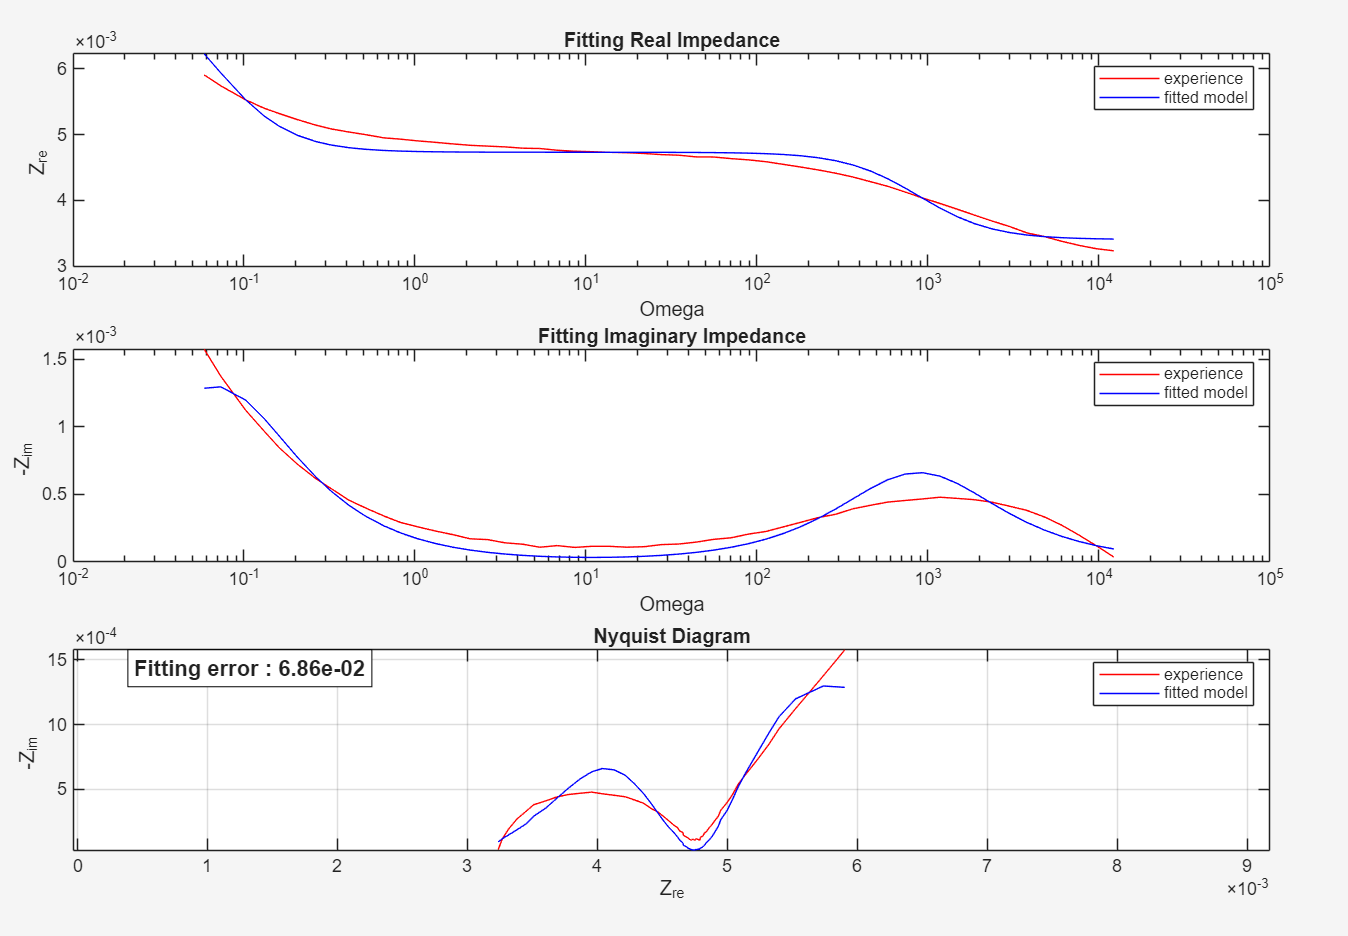

Results with Ank experimental data

### Fitting PXD Model

We also worked with the BattMo PXD model derivated from Chen's data. We fitted the impedance through BattMo's method explained before, in the code computeImpedance().

function [Z_real, Z_imag, omegas] = load_chen_data()

    ne      = 'NegativeElectrode';
    pe      = 'PositiveElectrode';
    elyte   = 'Electrolyte';
    thermal = 'ThermalModel';
    co      = 'Coating';
    am      = 'ActiveMaterial';
    itf     = 'Interface';
    sd      = 'SolidDiffusion';
    ctrl    = 'Control';
    cc      = 'CurrentCollector';
    
    mrstModule add ad-core mrst-gui mpfa agmg linearsolvers
    
    jsonstruct_material = parseBattmoJson(fullfile('ParameterData','ParameterSets','Chen2020','chen2020_lithium_ion_battery.json'));
    jsonstruct_geometry = parseBattmoJson(fullfile('Examples', 'JsonDataFiles', 'geometryChen.json'));
    
    jsonstruct = mergeJsonStructs({jsonstruct_material, ...
                                   jsonstruct_geometry});


    
    includeDoubleLayer = true;
    
    if includeDoubleLayer
    
        jsonstruct.(ne).(co).(am).(itf).useDoubleLayerCapacity = true;
        jsonstruct.(ne).(co).(am).(itf).doubleLayerCapacitance = 30;
    
    end
    
    [model, inputparams, ~] = setupModelFromJson(jsonstruct);
    
    c_ne = 29.866*mol/litre; % initial concentration at negative electrode
    c_pe = 17.038*mol/litre; % initial concentration at positive electrode
    
    initstate = initStateChen2020(model, c_ne, c_pe);
    
    impsolv = ImpedanceSolver(inputparams, 'initstate', initstate, 'computeSteadyState', false);
    
    
    omegas = logspace(-4, 2, 50);
    Z = impsolv.computeImpedance(omegas);

    Z_real = real(Z);
    Z_imag = imag(Z);
end


[Z_re_exp, Z_im_exp, omega] = load_chen_data();


params0 = [0.05052, 1.12673, 59119.9, 0.03155, 11054.0];  % initial condition: C1>2*C2

a = 1000;

pmin = params0 / a;
pmax = params0 * a;
scales = [pmin, pmax];

feis = FittingEIS(params0, scales, Z_re_exp, Z_im_exp, omega);

[~, ~, best_params, fitting_error] = feis.optimizationBFGS();

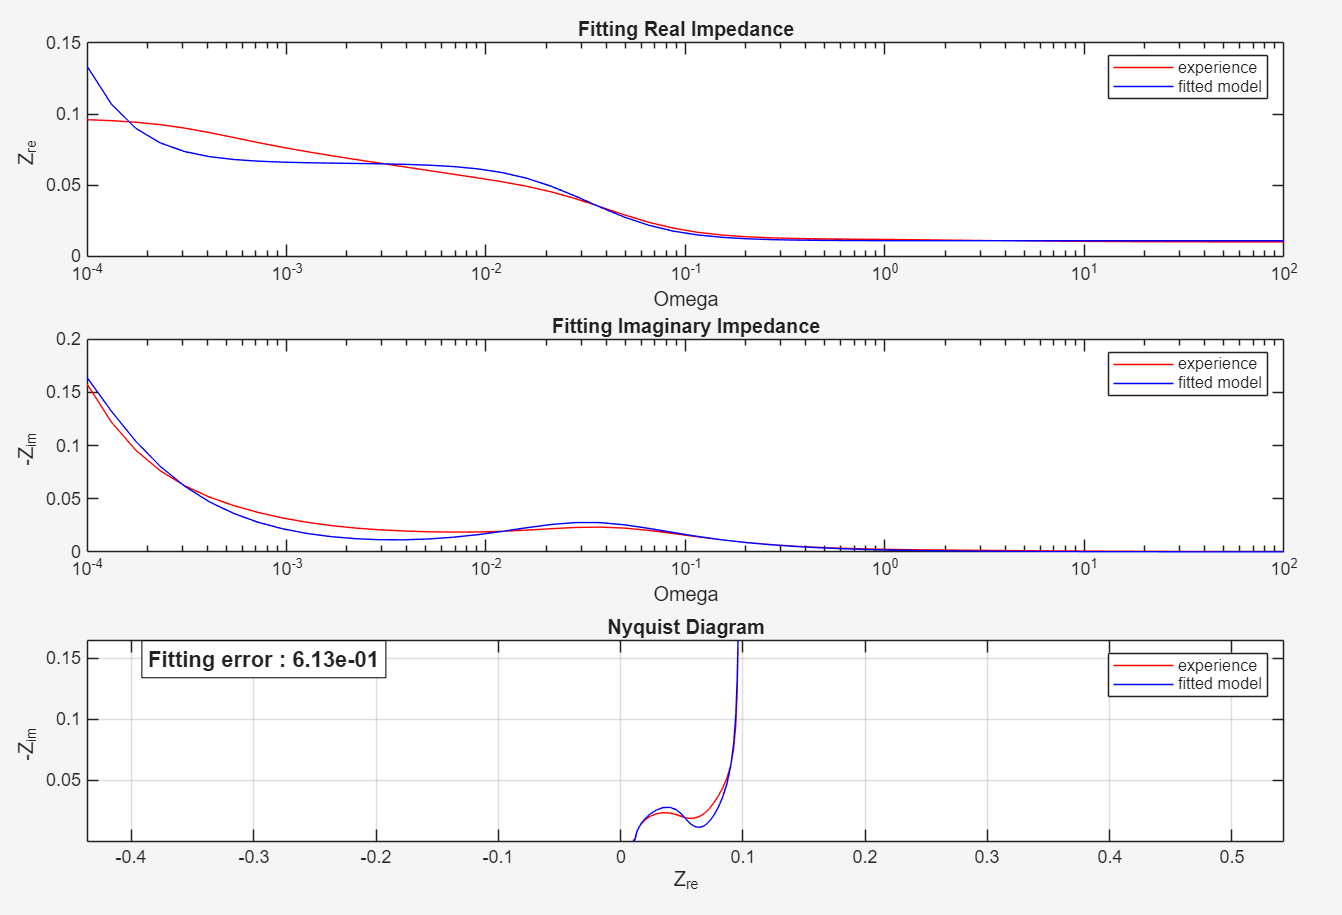

Results with Chen Synthetic model

## Discussion

- The fitting of synthetic data demonstrates the algorithm's accuracy, proving its ability to find a near-optimal solution—if one exists—even from distant initial parameters.

- A comparison between the experimental data and the optimal solution indicates that the ECM successfully reproduces the overall behavior, though the accuracy is frequency-dependent, being highest in the lower to mid-frequency ranges.

- Conversely, the PXD model exhibits good agreement with the fitted data, with accuracy improving further at higher frequencies.